# Regelungssysteme 2

# Programmierpraktikum

# Teil 2: Regelung verteilter Energienetze

addpath('functions')

## Linearisiertes Modell eines Energienetzes

Betrachtet wird folgendes linearisiertes Modell im Zustandsraum: Ein Energienetz besteht aus drei Kraftwerken $P_i$ mit den Zuständen ${\mathbf{x}}_i \in R^3$ für $i\in \text{ }\left\lbrace 1,2,3\right\rbrace$. Der Zustand eines Kraftwerks $P_i$ setzt sich jeweils aus der Einspeisespannung $x_{i,1}$, dem Einspeisestrom $x_{i,2}$ und der Generatorspannung $x_{i,3}$ zusammen, also ${\mathbf{x}}_i ={\left\lbrack \begin{array}{c}
x_{i,1} \text{ }\text{ } & x_{i,2}  & x_{i,3} 
\end{array}\right\rbrack }^T$.Gemessen werden können zunächst nur die Generatorspannungen jedes Kraftwerks über die Sensoren $y_i ,i\in \text{ }\left\lbrace 1,2,3\right\rbrace$, also ${\mathbf{C}}_i =\text{ }\left\lbrack \begin{array}{c}
0 & 0 & 1
\end{array}\right\rbrack$. Jedes Kraftwerk verfügt über genau einen Steuereingang $u_i ,i\in \text{ }\left\lbrace 1,2,3\right\rbrace$, der sich über ${\mathbf{B}}_i =\text{ }{\left\lbrack \begin{array}{c}
0\ldotp 9 & −1 & 0
\end{array}\right\rbrack }^T$ auf Einspeisespannung und Einspeisestrom auswirkt. Da die Kraftwerke im gleichen Netz verbunden sind, ergibt sich eine Kopplung der Kraftwerke über die Einspeisespannung. Die lokalen Dynamiken werden wie folgt beschrieben:


$$\begin{array}{l}
\dot{{\mathbf{x}}_i } ={\mathbf{A}}_{\mathit{ii}} {\mathbf{x}}_i +\sum_{j\ne i} {\mathbf{A}}_{\mathit{ij}} {\mathbf{x}}_j +B_i u_i \\
y_i ={\mathbf{C}}_i {\mathbf{x}}_i 
\end{array}$$


wobei ${\mathbf{A}}_{ii} \in R^{3x3}$die lokale Dynamikmatrix ist und ${\mathbf{A}}_{ij} \in R^{3x3}$ die Kopplung zwischen den Zuständen der verschiedenen Kraftwerke repräsentiert. Die Dynamik des gesamten Energienetzes lässt sich umschreiben als


$$\mathbf{\dot{x}} = A \mathbf{x}+B \mathbf{u}
\\
\mathbf{y} = C \mathbf{x}$$


wobei $\mathbf{x}={\left\lbrack \begin{array}{c}
{\mathbf{x}}_1^T  & {\mathbf{x}}_2^T  & {\mathbf{x}}_3^T 
\end{array}\right\rbrack }^T \in R^{9x1}$ der zusammengefasste Zustandsvektor, $\mathbf{y}=\text{ }{\left\lbrack \begin{array}{c}
y_1  & y_2  & y_3 
\end{array}\right\rbrack }^T$ die Spannungsmessungen und $\mathbf{u}=\text{ }{\left\lbrack \begin{array}{c}
u_1  & u_2  & u_3 
\end{array}\right\rbrack }^T$ die Steuereingänge des Netzwerkes sind. Falls nicht anders angegeben gilt:

A = [...
-2.445,  -0.16 ,  0  ,  -0.162,   0 	 ,   0 	,   -0.129 	,   0 		,  0 ;...
 2.557,  0     ,  0  ,  -0.007,   0 	 ,   0 	,   -0.006 	,   0 		,  0 ;...
 3.06 ,  0     ,  -1 ,   0.984,   0 	 ,   0 	,    0.785 	,   0 		,  0 ;...
-0.162,  0     ,  0  ,  -2.846,   -0.12,   0 	,   -0.111 	,   0 		,  0 ;...
-0.007,  0     ,  0  ,   2.552,   0 	 ,   0 	,   -0.005 	,   0 		,  0 ;...
 0.984,  0     ,  0  ,   3.672,   0 	 ,   -3 ,    0.673 	,   0 		,  0 ;...
-0.129,  0     ,  0  ,  -0.111,   0 	 ,   0 	,   -2.289 	,   -0.07 	,  0 ;...
-0.006,  0     ,  0  ,  -0.005,   0 	 ,   0 	,    2.564 	,   0 		,  0 ;...
 0.785,  0     ,  0  ,   0.673,   0 	 ,   0 	,    2.116 	,   0 		,  -2];   

B = [...
  0.9,  0  ,  0  ;...
 -1  ,  0  ,  0  ;...
  0  ,  0  ,  0  ;...
  0  ,  0.9,  0  ;...
  0  , -1  ,  0  ;...
  0  ,  0  ,  0  ;... 
  0  ,  0  ,  0.9;...
  0  ,  0  , -1  ;...
  0  ,  0  ,  0  ];

C = [...
  [0, 0, 1] , zeros(1,3), zeros(1,3); ...
  zeros(1,3), [0, 0, 1] , zeros(1,3); ...
  zeros(1,3), zeros(1,3), [0, 0, 1] ];

Die Kopplung der Kraftwerke ist an der Matrix $\mathbf{A}$ zu erkennen, die auch Einträge ungleich Null auf den Diagonalblöcken ${\mathbf{A}}_{ij} ,\text{ }i\ne j$ hat. Außerdem sind die Kraftwerke nicht vom gleichen Typ, da alle ${\mathbf{A}}_{ii}$ unterschiedlich sind.

Angenommen die Eingänge der verschiedenen Kraftwerke werden über folgendes Regelgesetz gesteuert.


$$\mathbf{u}=−\mathbf{Kx}+\mathbf{L}\omega ,\text{ }i\in \text{ }\left\lbrace 1,2,3\right\rbrace$$


wobei $K$ die Rückführmatrix, $L$ die Vorfiltermatrix und $\omega \in R^{3x1}$ die gewünschte Führungsgröße ist. Die für den Zustandsregler erforderliche Beobachtbarkeit der Zustände kann als gegeben angenommen werden.

## Aufgabe 1

`Entwerfen Sie zunächst einen zentralen Regler über die Rückführmatrix `$\mathbf{K}$`, sodass der geschlossene Regelkreis des Netzwerks die folgenden Pole hat und diese möglichst robust gegenüber Störungen in den Matrizen `$\mathbf{A}$` und `$\mathbf{B}$` sind. Geben Sie die Rückführmatrix `$\mathbf{K}$` aus.`

lambda_K = [-3.5, -4.5, -2.5, -3.2, -2.7, -1.1, -2.8, -0.2, -0.8]'; 

Wähle beliebige Parametervektoren, da keine Vorgaben:

p = rand(3,length(lambda_K))

p =     0.0594    0.6964    0.0924    0.6556    0.1088    0.1343    0.1683    0.3164    0.8929
    0.3158    0.1253    0.0078    0.7229    0.6318    0.0986    0.1962    0.2176    0.7032
    0.7727    0.1302    0.4231    0.5312    0.1265    0.1420    0.3175    0.2510    0.5557


Berechnung der Regelungseigenvektoren: ${\mathbf{v}}_{Ki} =\text{ }{\left(\mathbf{A}−\lambda_{Ki} \mathbf{I}\right)}^{−1} {\mathbf{Bp}}_i$

v_ki = zeros(9,length(lambda_K));
for i=1:length(lambda_K)
    v_ki(:,i) = (A - lambda_K(i) * eye(length(A))) \ B * p(:,i);
end
display(v_ki);

v_ki =     0.1785    0.2922    0.3787    1.1266   -1.7344   -0.0846   -3.2725   -0.0542   -0.4825
   -0.1454   -0.3205   -0.4240   -1.0991    1.5894    0.0738    2.9007   -0.8944    0.4216
   -0.6031   -0.2986   -0.7961   -2.7725    5.9618    3.7379   11.5624   -0.3600   -9.7355
    0.4979    0.0958   -0.8701    2.0065   -3.9780   -0.0361   -9.3341   -0.0396   -0.2506
   -0.4520   -0.0816    0.8884   -1.8223    3.5193   -0.0070    8.4254   -0.5868   -0.0855
   -4.8163   -0.4587   -4.1161  -45.2868  -56.9893   -0.1493 -194.3918   -0.0965   -0.7215
    0.6008    0.0726    1.1357    0.8633   -1.1634   -0.1012   -2.0555   -0.1062   -0.2855
   -0.6599   -0.0698   -1.3348   -0.8525    1.0468    0.1062    1.7452    0.1032    0.2153
   -1.1643   -0.1790   -4.2296   -3.3846    9.2865   -0.3387   16.5002   -0.1632   -0.9597


Berechnung der Rückführmatrix: $\mathbf{K}=\text{ }\left({\mathbf{p}}_1 ,{\mathbf{p}}_2 ,\ldotp \ldotp \ldotp \right){\left({\mathbf{v}}_{K1} ,{\mathbf{v}}_{K2} ,\ldotp \ldotp \ldotp \right)}^{−1}$

K_rand = p / v_ki  % Rückführmatrix durch zufällige Wahl von p

K_rand =    25.6953   21.8158   -0.0260  -40.0037  -36.0882    0.0100   92.0401   79.9697    0.2121
   -7.2658   -8.1451    0.0732   16.4806   13.3662   -0.0030  -70.4440  -61.8759    0.1831
   25.1315   24.1200   -0.0350  -44.7460  -40.1537    0.0047  122.6653  105.4551    0.1611


Verifiziere, ob Eigenwerte richtig platziert wurden:

EW_rand = eig(A - B * K_rand)  % Eigenwerte durch zufällige Wahl von p

EW_rand =    -4.5000
   -0.2000
   -0.8000
   -1.1000
   -3.5000
   -3.2000
   -2.8000
   -2.7000
   -2.5000


if round(sort(lambda_K),5) == round(sort(EW_rand),5), disp('The eigenvalues are placed as wanted.');
else, disp('The eigenvalues are placed wrong');
end

The eigenvalues are placed as wanted.


**Alternative:**

Entwurf der Rückführmatrix $\mathbf{K}$ durch setzen der Pole mittels `place `Befehl.

K_place = place(A, B, lambda_K)  % Rückführmatrix mittels place Befehl

K_place =    -1.5621   -4.6368    1.2451    7.2469    5.4427    0.0079  -24.7002  -21.8573   -0.0134
   -2.3447   -2.6488   -0.0268   -1.7277   -3.2394   -0.0517  -10.6463   -9.4741   -0.0100
    8.0903    8.0208    0.0827  -12.6507  -11.2855   -0.0045   45.0654   37.7542    0.2878


Verifiziere, ob Eigenwerte richtig platziert wurden:

EW_place = eig(A-B*K_place) % Eigenwerte durch Berechnung der Rückführmatrix mittels place Befehl

EW_place =    -4.5000
   -0.2000
   -0.8000
   -1.1000
   -3.5000
   -3.2000
   -2.5000
   -2.7000
   -2.8000


if round(sort(lambda_K),5) == round(sort(EW_place),5), disp('The eigenvalues are placed as wanted.');
else, disp('The eigenvalues are placed wrong');
end

The eigenvalues are placed as wanted.


Beide Methoden funktionieren also.

K = K_place;  % Da in aller Regel leicht "bessere" Lösung

## Aufgabe 2

`Verwenden Sie die Rückführmatrix `$\mathbf{K}$` aus 1). Zeigen Sie, dass es möglich ist für diese Rückführmatrix das Verhalten des gesamten Systems so anzupassen, dass es stationär genau ist. Geben Sie das Design der entsprechenden Vorfiltermatrix `${\mathbf{L}}_1$` an. Wählen Sie außerdem eine zufällige Vorfiltermatrix `${\mathbf{L}}_2$`. Angenommen, die Kraftwerksbetreiber sollen alle Generatorspannungen (`${\mathbf{x}}_{i,3}$`) um 1 (Volt) anheben. (Die Linearisierung bleibt weiterhin gültig.) Visualisieren Sie die Systemantworten des Energienetzes für `${\mathbf{L}}_1$` und `${\mathbf{L}}_2$`. Erläutern Sie kurz entscheidende Unterschiede und gehen Sie dabei auf das stationäre Verhalten ein.`

Während der Zustandsregler Abweichungen vom trivialen Gleichgewichtspunkt stabilisiert, verhindert der Vorfilter konstante Abweichungen des trivialen Zustandspunktes bezüglich der (konstanten) Führungsgröße. Zunächst müssen hierfür die Vorbedingungen überprüft werden:

- Ist das geregelte System (asymptitisch) Stabil: $\Re \left\lbrace {\text{ }\lambda }_{\mathit{Ki}} \left(\mathbf{A}−\mathit{\mathbf{BK}}\right)\text{ }\right\rbrace <0\text{ }\forall i$?

lambda_ki = eig(A-B*K)

lambda_ki =    -4.5000
   -0.2000
   -0.8000
   -1.1000
   -3.5000
   -3.2000
   -2.5000
   -2.7000
   -2.8000


if lambda_ki < 0, disp('The controlled system is stable.')
else, disp('The controlled system is not stable.')
end

The controlled system is stable.


- Ist $\nu =0$ eine invariante Nullstelle: $det\left({\mathbf{C}\left(\mathit{\mathbf{BK}}−\mathbf{A}\right)}^{−1} \mathbf{B}\right)=0$?

matrix_inv = C/(B*K-A) * B

matrix_inv =     0.2723   -0.0339    0.1437
   -0.0152    0.0491    0.0023
    0.0789    0.0060    0.0570


if round(det(A),5) ~= 0, disp('v=0 is not an invariant root.')
else, disp('v=0 is an invariant root.')
end

v=0 is not an invariant root.


**Alternativ (laut Lösung):**

if all(svd(A-B*K) > 1e-5) && all(svd(C/(A-B*K)*B) > 1e-5), disp('Is inversable and thus exactly stable');
else, disp('Is not inverseable and thus it is not a stationary exact system');
end

Is inversable and thus exactly stable


Da beide Vorbedingungen erfüllt sind, ergibt sich der Vorfilter ${\mathbf{L}}_1$ für stationäre Genauigkeit als:

L_1 = inv(C/(B*K-A)*B)

L_1 =    18.1680   18.2074  -46.5399
    6.8243   27.2995  -18.2894
  -25.8617  -28.0586   83.8850


Die zufällige Vorfiltermatrix ${\mathbf{L}}_2$wird gewählt zu:

L_2 = rand(size(L_1))

L_2 =     0.1844    0.9138    0.3134
    0.2120    0.7067    0.1662
    0.0773    0.5578    0.6225


Systemantwort des Energienetzes für ${\mathbf{L}}_1$:

sys_L1 = ss(A-B*K, B*L_1,C,0)


sys_L1 =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     -1.039      4.013     -1.121     -6.684     -4.898   -0.00713       22.1      19.67
   x2     0.9949     -4.637      1.245       7.24      5.443   0.007922     -24.71     -21.86
   x3       3.06          0         -1      0.984          0          0      0.785          0
   x4      1.948      2.384     0.0241     -1.291      2.795    0.04649      9.471      8.527
   x5     -2.352     -2.649   -0.02678     0.8243     -3.239   -0.05166     -10.65     -9.474
   x6      0.984          0          0      3.672          0         -3      0.673          0
   x7      -7.41     -7.219    -0.0744      11.27      10.16    0.00409     -42.85     -34.05
   x8      8.084      8.021    0.08267     -12.66     -11.29  -0.004544      47.63      37.75
   x9      0.785          0          0      0.673          0          0      2.116          0
 
              x9
   x1    0.01208
   x2

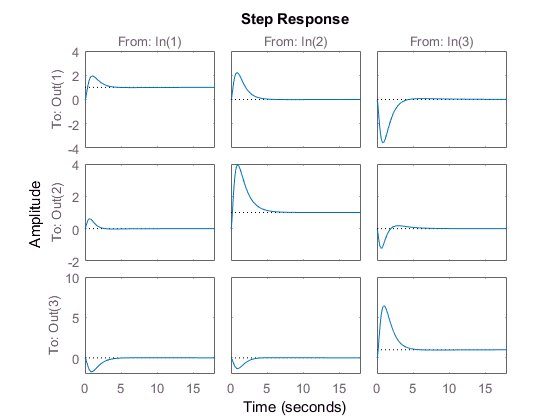

stepplot(sys_L1)

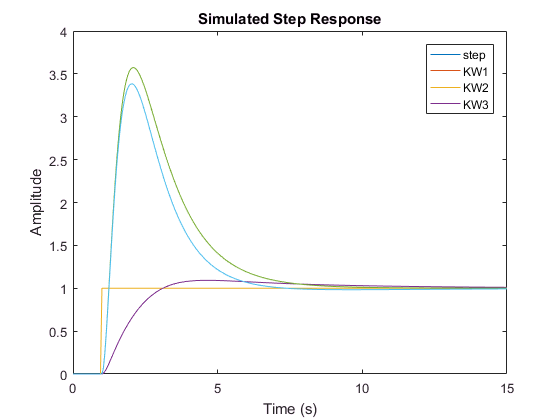

% define the sample rate of the equivalent discrete-time model
Ts = 1/20; 
% convert the system to the equivalent discrete-time model
sysd = c2d(sys_L1,Ts);
% define how long a step response you'd like to compute
t = 0:Ts:15; % time-grid for the plot
nSmp = length(t); % total number of samples to be computed
% initializations
y = NaN(3, nSmp); % output vector
u = [zeros(3,1/Ts),ones(3, nSmp-1/Ts)]; % unit step input 
X = zeros(9,1); % state vector, initialized to 0
% compute the samples of the step-response
%  (i prefer to use vectorized form to keep the code concise)
for i=1:nSmp
    y(:,i) = sysd.C * X + sysd.D * u(:,i);
    X = sysd.A * X + sysd.B * u(:,i);
end
% plot simulated discrete-time step response
figure;
plot(t, [u;y])
xlabel('Time (s)');
ylabel('Amplitude');
title('Simulated Step Response');
legend('step','KW1','KW2','KW3');

Wie zu sehen ist, zeigen beide Methoden (die integrierte `stepplot` Funktion, sowie eine manuelle Implementierung), dass das gegebene System stationär genau ist: Der Ausgang folgt dem Eingangssignal (asymptotisch).

Systemantwort des Energienetzes für ${\mathbf{L}}_2$:

sys_L2 = ss(A-B*K, B*L_2,C,0)


sys_L2 =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     -1.039      4.013     -1.121     -6.684     -4.898   -0.00713       22.1      19.67
   x2     0.9949     -4.637      1.245       7.24      5.443   0.007922     -24.71     -21.86
   x3       3.06          0         -1      0.984          0          0      0.785          0
   x4      1.948      2.384     0.0241     -1.291      2.795    0.04649      9.471      8.527
   x5     -2.352     -2.649   -0.02678     0.8243     -3.239   -0.05166     -10.65     -9.474
   x6      0.984          0          0      3.672          0         -3      0.673          0
   x7      -7.41     -7.219    -0.0744      11.27      10.16    0.00409     -42.85     -34.05
   x8      8.084      8.021    0.08267     -12.66     -11.29  -0.004544      47.63      37.75
   x9      0.785          0          0      0.673          0          0      2.116          0
 
              x9
   x1    0.01208
   x2

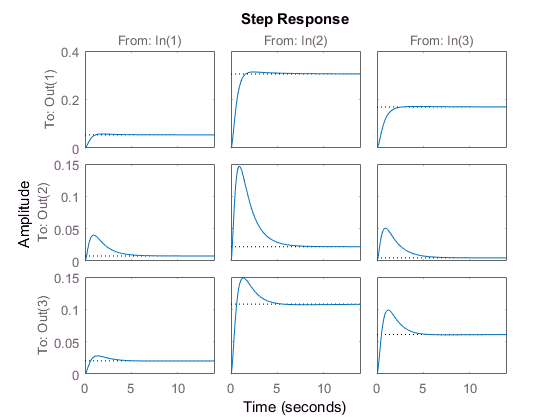

stepplot(sys_L2)

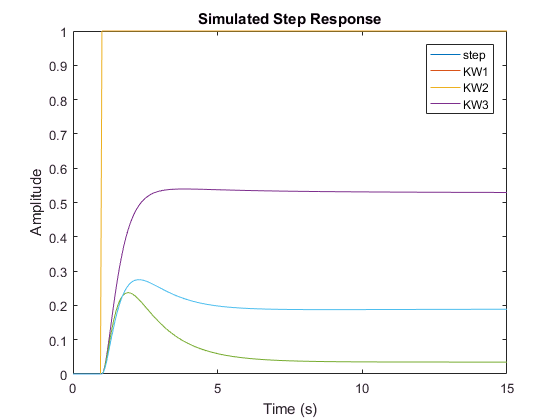

% define the sample rate of the equivalent discrete-time model
Ts = 1/20; 
% convert the system to the equivalent discrete-time model
sysd = c2d(sys_L2,Ts);
% define how long a step response you'd like to compute
t = 0:Ts:15; % time-grid for the plot
nSmp = length(t); % total number of samples to be computed
% initializations
y = NaN(3, nSmp); % output vector
u = [zeros(3,1/Ts),ones(3, nSmp-1/Ts)]; % unit step input 
X = zeros(9,1); % state vector, initialized to 0
% compute the samples of the step-response
%  (i prefer to use vectorized form to keep the code concise)
for i=1:nSmp
    y(:,i) = sysd.C * X + sysd.D * u(:,i);
    X = sysd.A * X + sysd.B * u(:,i);
end
% plot simulated discrete-time step response
figure;
plot(t, [u;y])
xlabel('Time (s)');
ylabel('Amplitude');
title('Simulated Step Response');
legend('step','KW1','KW2','KW3');

Es ist klar zu erkennen, dass bei zufälliger Wahl der Vorfiltermatrix weniger/keine stationäre Genauigkeit erziehlt wird, da das System zwar konvergiert, jedoch gegen einen falschen Wert (nicht 1!).

Als verantwortlicher Regelungstechnikingenieur des ersten Kraftwerks beschließen Sie etwas mehr in die eigene Tasche zu wirtschaften und zapfen jetzt das Stromnetz des Kraftwerks illegal an. Sie überlegen die Generatorspannung ${\mathbf{x}}_{1,3}$ oder den Einspeisestrom ${\mathbf{x}}_{1,2}$ anzuzapfen. Ihr Anzapfen beeinfusst das Verhalten des Kraftwerks unvorhersehbar und wird daher als Störung modelliert. Die Gesamtdynamik ändert sich dadurch wie folgt:


$$\mathbf{\dot{x}} = A \mathbf{x}+B \mathbf{u}+\mathbf{N} d
\\
\mathbf{y} = C \mathbf{x}
$$


wobei $\mathbf{N}$ die Störmatrix und $d\in R$ der Störungseingang ist. Falls Sie den Einspeisestrom ${\mathbf{x}}_{1,2}$ anzapfen ergibt sich $N$ als $N_1 ={\left\lbrack \begin{array}{c}
0 & −1\ldotp 2 & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack }^T$. Falls Sie die Generatorspannung $x_{1,3}$ anzapfen ergibt sich N als $N_2 =\text{ }{\left\lbrack \begin{array}{c}
0 & 0 & 2 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack }^T$. Um zu verhindern, dass Ihr Chef, der Betreiber des ersten Kraftwerks, und andere Betreiber des Energienetzes davon Wind bekommen entwerfen Sie einen Zustandsregler $u=−\mathit{\mathbf{Kx}}$ der das Energienetz so regelt, dass für alle Zeiten t > 0, die Änderung der Last ihres Kraftwerks ($d\left(t\right)$) nicht am Ausgang, also bei den Spannungssensoren, messbar ist.

N_1 = [0; -1.2; 0; 0; 0; 0; 0; 0; 0];
N_2 = [0;  0  ; 2; 0; 0; 0; 0; 0; 0];

## Aufgabe 3

`Zeigen Sie, ob es grundsätzlich für i) anzapfen des Einspeisestroms ii) anzapfen der Generatorspannung möglich ist.`

**Störentkopplungsbedingung** ${\mathbf{C}\text{ }\mathbf{v}}_{Ki} =0,\mathbf{N}\text{ }\subseteq X_{K,\overline{b} } =\left\lbrace {\mathbf{v}}_{Ki} \right\rbrace$: Bestimmt linear unabhängige Vektoren ${\mathbf{v}}_{Ki}$ für die die Bedingung $\mathbf{C}\text{ }{\mathbf{v}}_{Ki} =0$erfüllt ist. Es ergibt sich der nicht beobachtbare Teil des Zustandraumes $X_{K,\overline{b} } =\left\lbrace {\mathbf{v}}_{Ki} \right\rbrace$mit nicht beobachtbaren Basisvektoren ${\mathbf{v}}_{Ki}$. Lassen sich alle Spaltenvektoren von $\mathbf{N}$als Linearkombination der Basisvektoren ${\mathbf{v}}_{Ki}$ darstellen? Wenn ja, dann ist **Störentkoppelung** prinzipiell möglich.

v_ki_stoer = null(C) % element R^9x?

v_ki_stoer =      0     0     0     0     0     1
     0     0    -1     0     0     0
     0     0     0     0     0     0
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     0


nV_ki_stoer = size(v_ki_stoer,2)

nV_ki_stoer = 6


if rank([v_ki_stoer,N_1]) <= nV_ki_stoer, disp('N_1 is element of subspace {v_Ki}. -> Stoeentkoppelbar');
else, disp('N_1 is not element of subspace {v_Ki}. -> Nicht Stoeentkoppelbar');
end

N_1 is element of subspace {v_Ki}. -> Stoeentkoppelbar


if rank([v_ki_stoer,N_2]) <= nV_ki_stoer, disp('N_2 is element of subspace {v_Ki}. -> Stoeentkoppelbar');
else, disp('N_2 is not element of subspace {v_Ki}. -> Nicht Stoeentkoppelbar');
end

N_2 is not element of subspace {v_Ki}. -> Nicht Stoeentkoppelbar


Wie klar zu erkennen ist, ist nur ${\mathbf{N}}_1$ als Linearkombination der Basisvektoren ${\mathbf{v}}_{Ki}$ darstellbar, weshalb nur für den ersten Fall (Anzapfen des Generatorstroms) eine Störentkoppelung möglich ist.

## Aufgabe 4

`Entwerfen Sie für i) oder ii) aus Aufgabe 3 (je nachdem für welchen Fall die Entkopplung möglich ist) den Zustandsregler `$K$`, sodass das geregelte System möglichst viele der Eigenwerte aus Aufgabe 1 hat und setzen Sie für die Werte der zugehörigen Parametervektoren `$p_i$` zufällige Vektoren der entsprechenden Größe. Visualisieren Sie die Auswirkung der Störung auf die Ausgänge wenn das System mit dem Zustandsregler geregelt wird. Visualisieren und vergleichen Sie außerdem die Auswirkung der Störung auf den Ausgang, wenn Sie `$K$`aus Aufgabe 1 verwenden.`

Aus 3) wissen wir, dass nur für den ersten Fall (Anzapfen der Generatorstroms) eine Störentkoppelung möglich ist.

- Bestimme k (= Anzahl linear unabhängiger Vektoren ${\mathbf{v}}_{Ki}$, die benötigt werden um alle Spaltenvektoren von $\mathbf{N}$darzustellen) invariante Nullstellen: $det\text{ }\mathbf{R}\left(\eta \right)=\left\lbrack \begin{array}{c}
\eta \mathbf{I}−\mathbf{A} & −\mathbf{B}\\
\mathbf{C} & 0
\end{array}\right\rbrack =0$! 

% Tiny script to find one minimal amount of vectors to represent another vector as a linear combination
combinations = [];
v_ki_solution = [];
for i = 1:nV_ki_stoer
    %combis = perms(1:i)
    combis = combnk(1:nV_ki_stoer,i);
    for j = 1:size(combis,1)
        v_ki_combi = v_ki_stoer(:,combis(j,:));
        if rank([v_ki_combi,N_1]) == i
            v_ki_solution = v_ki_combi
            break;
        end
    end
    if ~isempty(v_ki_solution)
        break;
    end
end

v_ki_solution =      0
    -1
     0
     0
     0
     0
     0
     0
     0


k = size(v_ki_solution,2)

k = 1

In unserem Fall ist $k=1$, d.h. dass wir eine invariante Nullstelle benötigen.

sys = ss(A,B,C,0)


sys =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8      x9
   x1  -2.445   -0.16       0  -0.162       0       0  -0.129       0       0
   x2   2.557       0       0  -0.007       0       0  -0.006       0       0
   x3    3.06       0      -1   0.984       0       0   0.785       0       0
   x4  -0.162       0       0  -2.846   -0.12       0  -0.111       0       0
   x5  -0.007       0       0   2.552       0       0  -0.005       0       0
   x6   0.984       0       0   3.672       0      -3   0.673       0       0
   x7  -0.129       0       0  -0.111       0       0  -2.289   -0.07       0
   x8  -0.006       0       0  -0.005       0       0   2.564       0       0
   x9   0.785       0       0   0.673       0       0   2.116       0      -2
 
  B = 
        u1   u2   u3
   x1  0.9    0    0
   x2   -1    0    0
   x3    0    0    0
   x4    0  0.9    0
   x5    0   -1    0
   x6    0    0    0
   x7    0    0  0.9
   x8    0    0   -1
   x9 

invariant_zeros = tzero(sys)

invariant_zeros =    -0.0778
   -0.1333
   -0.1778


invar_zero = invariant_zeros(1) % pick randomly one invariant zero

invar_zero = -0.0778

Diese wird als ein Regelungseigenwert festgelegt:

new_eigenvalues = [invar_zero; lambda_K(1:end-1)]

new_eigenvalues =    -0.0778
   -3.5000
   -4.5000
   -2.5000
   -3.2000
   -2.7000
   -1.1000
   -2.8000
   -0.2000


Wähle beliebige Parametervektoren, bis auf den zur invarianten Nullstellen korrespondierenden Parametervektor: 


$$\begin{array}{l}
\left(\lambda \mathbf{I}−\mathbf{A}\right){\mathbf{v}}_{Ki} =−\mathbf{Bp}\\
{\mathbf{p}}^T {\mathbf{B}}^T =−{\mathbf{v}}_{Ki}^T {\left(\lambda \mathbf{I}−\mathbf{A}\right)}^T \\
{\mathbf{p}}^T {\mathbf{B}}^T \mathbf{B}=−{\mathbf{v}}_{Ki}^T {\left(\lambda \mathbf{I}−\mathbf{A}\right)}^T \mathbf{B}\\
{\mathbf{p}}^T =−{\mathbf{v}}_{Ki}^T {\left(\lambda \mathbf{I}−\mathbf{A}\right)}^T \mathbf{B}{\left({\mathbf{B}}^T \mathbf{B}\right)}^{−1} 
\end{array}$$


%pinv = -(B'*B)\B'*(invar_zero*eye(size(A))-A)*N_1 % From solution...
pinv = -v_ki_solution'*(invar_zero*eye(size(A))-A)'*B/(B'*B) % My solution (seems to be more correct ;-) )

pinv =     0.1225         0         0


p = [ pinv' ,rand(3,length(new_eigenvalues)-1)]

p =     0.1225    0.9879    0.3968    0.4024    0.6207    0.1611    0.3508    0.5306    0.3353
         0    0.1704    0.0740    0.9828    0.1544    0.7581    0.6855    0.8324    0.2992
         0    0.2578    0.6841    0.4022    0.3813    0.8711    0.2941    0.5975    0.4526


Berechnung der Regelungseigenvektoren: ${\mathbf{v}}_{Ki} =\text{ }{\left(\mathbf{A}−\lambda_{Ki} \mathbf{I}\right)}^{−1} {\mathbf{Bp}}_i$

v_ki = zeros(9,length(new_eigenvalues));
v_ki(:,1) = v_ki_solution; %From solution: N_1.. I had: v_ki_solution;
for i=2:length(new_eigenvalues)
    v_ki(:,i) = (A - new_eigenvalues(i) * eye(size(A))) \ B * p(:,i);
end
display(v_ki);

v_ki =          0    0.8116    0.1824   -0.8543    0.8088   -2.3661   -0.1920  -11.5061    0.0225
   -1.0000   -0.8739   -0.1913    0.7038   -0.8376    2.1635    0.1244   10.2212   -1.9730
         0   -1.2535   -0.2434    3.8559   -1.6389    8.1702   10.5753   40.4804   -0.1927
         0    0.4215    0.0730   -2.9684    0.7207   -6.3413   -0.3345  -31.9995   -0.0629
         0   -0.3540   -0.0572    2.6340   -0.6204    5.7058    0.1508   28.8252   -0.6982
         0   -5.0966   -0.4252  -23.9078  -19.0180  -86.5481   -0.8095 -670.5637   -0.1239
         0    0.2998    0.2829   -0.3167    0.5371   -0.5213   -0.1793   -7.8580   -0.2054
         0   -0.2913   -0.3129    0.1559   -0.5468    0.1554    0.1480    6.9005    0.3698
         0   -1.0369   -0.3163    6.6771   -1.8803   10.3259   -0.8392   58.9944   -0.2552


Berechnung der Rückführmatrix: $\mathbf{K}=\text{ }\left({\mathbf{p}}_1 ,{\mathbf{p}}_2 ,\ldotp \ldotp \ldotp \right){\left({\mathbf{v}}_{K1} ,{\mathbf{v}}_{K2} ,\ldotp \ldotp \ldotp \right)}^{−1}$

K_stoer = p / v_ki  % Rückführmatrix

K_stoer =     0.2809   -0.1225    0.2671    3.1924    6.0743    0.0130   40.8996   35.2126    0.1418
    1.1304         0   -0.0476   -2.9316   -4.5192   -0.0017  -24.9932  -22.1169    0.1237
   -2.6576         0    0.5658    7.8042   12.1410    0.0101   90.5893   76.6898    0.6152


K_stoer_place = place(A, B, new_eigenvalues) % Alternativ, Only this one is working...

K_stoer_place =     5.3128    1.9240    1.7405    4.0724    4.1191    0.0080    0.2295    0.1205   -0.0366
   -4.5056   -3.5322   -0.7930   -7.3448   -8.9315   -0.0655   -1.4408   -1.5369   -0.0140
   -1.9750   -1.9070   -0.1669   -1.0762   -1.6533    0.0050    1.2097   -0.7304    0.4164


Verifiziere, ob Eigenwerte richtig platziert wurden:

EW_stoer = eig(A - B * K_stoer)  % Eigenwerte durch zufällige Wahl von p

EW_stoer =    -4.5000
   -0.1766
   -0.2000
   -1.1000
   -3.5000
   -2.5000
   -2.7000
   -2.8000
   -3.2000


if round(sort(new_eigenvalues),5) == round(sort(EW_stoer),5), disp('The eigenvalues are placed as wanted.');
else, disp('The eigenvalues are placed wrong');
end

The eigenvalues are placed wrong


EW_stoer_place = eig(A - B * K_stoer_place)  % Eigenwerte durch zufällige Wahl von p

EW_stoer_place =    -4.5000
   -0.2000
   -0.0778
   -1.1000
   -3.5000
   -3.2000
   -2.5000
   -2.8000
   -2.7000


if round(sort(new_eigenvalues),5) == round(sort(EW_stoer_place),5), disp('The eigenvalues are placed as wanted.');
else, disp('The eigenvalues are placed wrong');
end

The eigenvalues are placed as wanted.


Nun wird die Sprungantwort des neu geregelten Systems (mit `K_stoer`) mit der vorherigen Version (mit `K_place`) verglichen. Hierzu wird ein neues System erzeugt, das anstatt von $\mathbf{u}$ nur noch den Eingang $d$ hat ($\Rightarrow \mathbf{B}:=\mathbf{N}$).

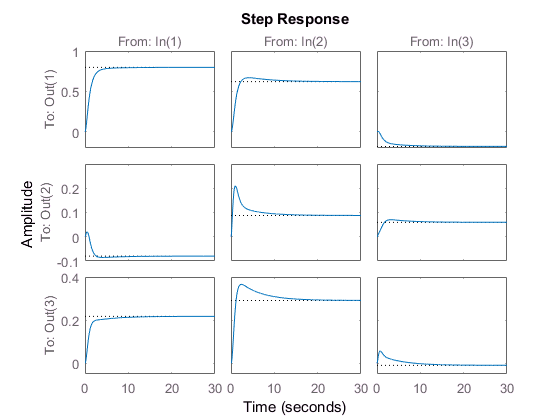

sys_N1_K_stoer = ss(A-B*K_stoer, B, C, 0);
stepplot(sys_N1_K_stoer)

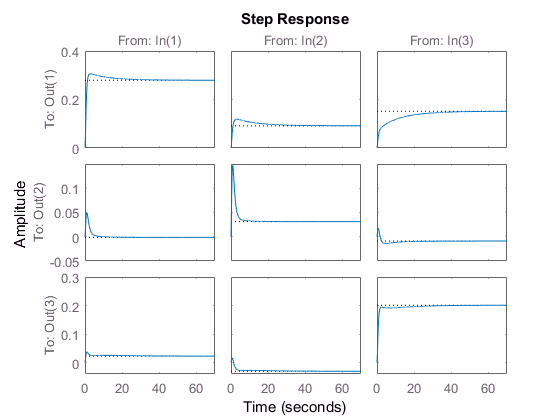

sys_N1_K_stoer_place = ss(A-B*K_stoer_place, B, C, 0);
stepplot(sys_N1_K_stoer_place)

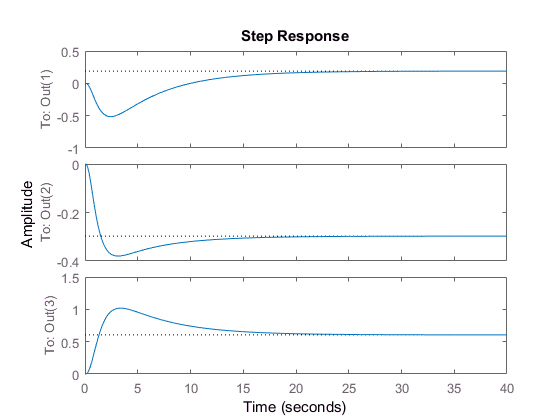

sys_N1_K_place = ss(A-B*K_place, N_1, C, 0);
stepplot(sys_N1_K_place)

TODO: Eigene Rechnung nicht richtig...

Ihr Chef vermutet das Leck in den anderen Kraftwerken und bietet Ihnen daher einen Bonus für den Fall, dass Sie eine dynamische Entkopplung der Kraftwerke durch entsprechende Regelung hinbekommen. Sie entscheiden daher keinen Strom mehr abzuzapfen und die Kraftwerke dynamisch zu entkoppeln. Damit führt eine Änderung des Sollwertes in einem Teilsystem nur zu einer lokalen Änderung während die anderen Teilsysteme konstant bleiben. Dadurch kann ein MIMO System als Reihe von gekoppelten SISO Systemen analysiert werden. In dieser Aufgabe soll eine Regelungsansatz für die dynamische Entkopplung des Energienetzes entworfen werden.

Matrizen $\mathbf{A},\mathbf{B}\text{ }und\text{ }\mathbf{C}$ werden wie oben gegeben angenommen. Die Stärung entfällt.

## Aufgabe 5

`Zeigen Sie, dass ein stabiler entkoppelnder Regler für das gegebene Energienetz mit Matrizen `$\mathbf{A},\mathbf{B}\text{ }und\text{ }\mathbf{C}$` existiert.`

- Bestimme die **Gesamtdifferenzenordnung **$\delta_{Gesamt}$: Wenn $\delta_{\text{Gesamt}} <n$ , dann existieren Eigenwerte, die nicht als Pole von $\mathbf{G}$ auftreten. Diese werden in invariante Nullstellen verschoden. Dann ist die interne Stabilität (Stabilität der Nulldynamik) zu überprüfen. Falls $\Re \left(\eta \right)<0$ nicht gilt, dann ist eine Entkoppelungsregelung instabil, ansonsten ist "alles gut".

Gesamtdifferenzenordnung: $\delta_{Gesamt} =\sum_i \delta_i \text{ }\text{ }\text{ }mit\text{    }{\mathbf{c}}_i^T {\mathbf{A}}^j \mathbf{B}=0,\forall j=0,\ldotp \ldotp \delta_i −2\text{   }und\text{  }{\mathbf{c}}_i^T {\mathbf{A}}^{\delta_i −1} \mathbf{B}\ne 0$

% Tiny script for calculating the relative degree..
d = zeros(1,size(C,1));
for i = 1:size(C,1)
    j = 0;
    while C(i,:)*(A^j)*B == 0
        j = j+1;
    end
    d(i) = j+1;
end
disp(d)

     2     2     2



delta_gesamt = sum(d)

delta_gesamt = 6

if delta_gesamt == rank(A), disp('Entkoppelungsregelung stabil');
else
    invzeros = tzero(ss(A,B,C,0))
    if any(real(invzeros) >= 0), disp('Entkoppelungsregelung instabil');
    else, disp('Entkoppelungsregelung stabil');
    end
end

invzeros =    -0.0778
   -0.1333
   -0.1778


Entkoppelungsregelung stabil


E = zeros(size(C,1)); % Entkoppelungsmatrix
for i=1:size(C,1)
    E(i,:) = C(i,:)*(A^d(i))*B;
end
disp(E)

   -9.2325   -3.8125   -2.7223
   -5.2782  -19.0899   -3.6375
   -3.3586   -3.1803   -8.1782



## Aufgabe 6

`Den einzelnen Kraftwerken soll durch die Entkopplungsregelung folgendes Folgeverhalten eingeprägt werden:`


$$\begin{array}{l}
\frac{Y_1 \left(s\right)}{W_1 \left(s\right)}=\frac{100}{s^2 +10s+50}\\
\frac{Y_2 \left(s\right)}{W_2 \left(s\right)}=\frac{50}{s^2 +5s+20}\\
\frac{Y_3 \left(s\right)}{W_3 \left(s\right)}=\frac{10}{s^2 +s+1}
\end{array}$$


`Entwerfen Sie eine entsprechende Vor�ltermatrix `$L$` und einen Regler `$K$` und zeigen Sie, dass das gewünschte Verhalten erreicht  wird.`

- **Entkoppelbarkeitsbedingung: **$det\text{ }\mathbf{E}\ne 0$

det_E = det(E)

det_E = -1.0878e+03

if round(det_E,5) ~= 0, disp('Entkoppelbarkeitsbedingung erfüllt!');
else, disp('Entkoppelbarkeitsbedingung nicht erfüllt!');
end

Entkoppelbarkeitsbedingung erfüllt!


- Bestimmt $\Gamma =diag\left(\gamma_1 ,\ldotp \ldotp \ldotp ,\gamma_q \right),\text{ }mit\text{  }\gamma_i :Y_i \left(s\right)=\text{ }\frac{\gamma_i }{s^{\delta_i } +\ldotp \ldotp \ldotp +M_{i1} s+M_{i0} }∗W_i \left(s\right)$

Gamma = diag([100,50,10])

Gamma =    100     0     0
     0    50     0
     0     0    10


M = [50,10;20,5;1,1]

M =     50    10
    20     5
     1     1


L = E \ Gamma % = E^-1 * Gamma

L =   -13.2891    1.0352    0.3503
    2.8452   -3.0504    0.1766
    4.3511    0.7611   -1.4353


- Reglermatrix $K$: $\mathbf{K}={\mathbf{E}}^{−1} \left\lbrack \begin{array}{c}
{\mathbf{c}}_1^T {\mathbf{A}}^{\delta_1 } +\sum_{\nu =0}^{\delta_1 −1} M_{1\nu } {\mathbf{c}}_1^T {\mathbf{A}}^{\nu } \\
\ldotp \ldotp \ldotp \\
{\mathbf{c}}_q^T {\mathbf{A}}^{\delta_q } +\sum_{\nu =0}^{\delta_q −1} M_{q\nu } {\mathbf{c}}_q^T {\mathbf{A}}^{\nu } 
\end{array}\right\rbrack$ , wobei  die zweite Matrix im folgenden als `P` bezeichnet wird

% Tiny script to calculate P
P = zeros(size(C));
for i=1:size(C,1)
    M_sum = 0;
    for v=1:d(i)-1
        M_sum = M_sum + M(i,v+1)*C(i,:)*A^v;
    end
    P(i,:) = C(i,:)*A^d(i)+M_sum;
end
disp(P)

   19.7976   -0.4896   -9.0000    5.4727   -0.1181         0    4.7642   -0.0550         0
   -1.1196   -0.1574         0   -3.3406   -0.4406   -6.0000   -0.7290   -0.0471         0
   -3.0863   -0.1256         0   -2.9504   -0.0808         0   -7.1355   -0.1481    2.0000



K = E \ P

K =    -2.7622    0.0574    1.1960   -0.8998    0.0037   -0.1242   -0.8981    0.0011    0.0701
    0.5771   -0.0065   -0.2561    0.3074    0.0221    0.3661    0.0540   -0.0013    0.0353
    1.2873   -0.0057   -0.3916    0.6107   -0.0003   -0.0913    1.2204    0.0182   -0.2871


Ihr Chef, der Betreiber des Kraftwerks 1, hat sich durch o.g. Anschuldigungen bei den anderen Kraftwerksbetreibern sehr unbeliebt gemacht. Die Kraftwerksbetreiber stehen daher kurz davor die Kooperation (Austausch der Messdaten) aufzukündigen. Ihr Chef bittet Sie daher zu prüfen, ob eine stabile Regelung allein mit lokalen Messungen und Reglern möglich ist. Es soll sich dabei um drei lokale PD-Regler für jedes Kraftwerk einzeln handeln:


$$\begin{array}{l}
K_1 \left(s\right)=5+s\\
K_2 \left(s\right)=5+2s\\
K_3 \left(s\right)=10+s
\end{array}$$


Verwenden Sie das direkte Nyquistverfahren zum Entwurf dezentraler Regler.

## Aufgabe 7

`Erstellen Sie Nyquist-Ortskurven f�ur die einzelnen Übertragungsfunktionen der offenen Ketten der Eingrößenregelkreise. Für Sie eine manuelle Abfrage ein wie oft der kritische Punkt durch die Ortskurven umschlungen wird und ziehen die entsprechenden Schlussfolgerungen über die Stabilität.`

K_pd = [tf([1 5],1), tf(0), tf(0); tf(0), tf([2 5],1), tf(0); tf(0), tf(0), tf([1 10],1)]


K_pd =
 
  From input 1 to output...
   1:  s + 5
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
   2:  2 s + 5
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  s + 10
 
Continuous-time transfer function.



G_ol = K_pd * tf(sys)


G_ol =
 
  From input 1 to output...
          2.754 s^6 + 28.17 s^5 + 93.14 s^4 + 112.4 s^3 + 33.77 s^2 + 3.706 s + 0.1348
   1:  -----------------------------------------------------------------------------------
       s^7 + 8.58 s^6 + 27.49 s^5 + 40.21 s^4 + 26.16 s^3 + 6.499 s^2 + 0.6528 s + 0.02249
 
          1.771 s^6 + 12.61 s^5 + 31.46 s^4 + 31.13 s^3 + 9.507 s^2 + 1.117 s + 0.04378
   2:  -----------------------------------------------------------------------------------
       s^7 + 10.58 s^6 + 42.65 s^5 + 80.02 s^4 + 66.76 s^3 + 18.24 s^2 + 1.913 s + 0.06746
 
         0.7065 s^6 + 10.47 s^5 + 38.74 s^4 + 47.9 s^3 + 15.05 s^2 + 1.761 s + 0.06963
   3:  ----------------------------------------------------------------------------------
       s^7 + 9.58 s^6 + 35.07 s^5 + 60.11 s^4 + 46.46 s^3 + 12.37 s^2 + 1.283 s + 0.04497
 
  From input 2 to output...
         0.8856 s^6 + 8.214 s^5 + 23.73 s^4 + 25.67 s^3 + 8.651 s^2 + 1.079 s + 0.04379
   1:  ---------------------------

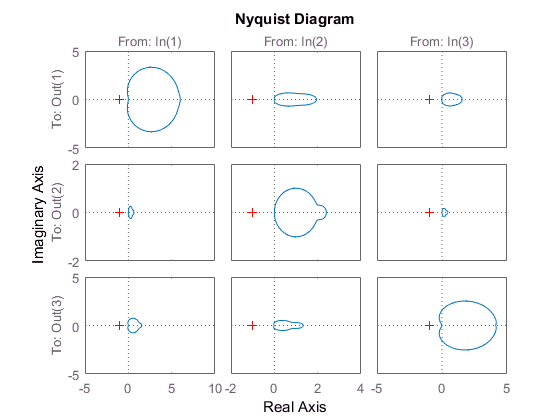

nyquist(G_ol)

Wie oft der kritische Punkt durch die Ortskurven umschlungen?

n_plus = sum(real(unique(pole(G_ol)))>0)

n_plus = 0

Mache eine Benutzereingabe diesbezüglich...

inputuser = input('How many times does the Nyquist plot go around -1 in clockwise? ')

inputuser = 0

if n_plus == inputuser, disp('Nyquist okay!');
else, disp('Nyquist now okay!');
end

Nyquist okay!


Da keiner der Nyquist Plots den kritischen Punkt $−1$ umschließt, ist das System laut Nyquist stabil.

## Aufgabe 8

`Überpr�ufen Sie die Diagonaldominanz der Rückführdifferenzmatrix indem Sie ein sinnvolles Raster von `$\omega$` untersuchen. Zeichnen Sie außerdem die Impulsantwort des geschlossenen gesamten Regelkreises. Welcher Schluss lässt sich aus den vorhergegangenen Ergebnissen ziehen und spiegelt sich dieser auch in der Impulsantwort des geschlossenen gesamten Regelkreises wider?`

F = eye(3) + G_ol


F =
 
  From input 1 to output...
       s^7 + 11.33 s^6 + 55.66 s^5 + 133.3 s^4 + 138.6 s^3 + 40.27 s^2 + 4.359 s + 0.1572
   1:  -----------------------------------------------------------------------------------
       s^7 + 8.58 s^6 + 27.49 s^5 + 40.21 s^4 + 26.16 s^3 + 6.499 s^2 + 0.6528 s + 0.02249
 
          1.771 s^6 + 12.61 s^5 + 31.46 s^4 + 31.13 s^3 + 9.507 s^2 + 1.117 s + 0.04378
   2:  -----------------------------------------------------------------------------------
       s^7 + 10.58 s^6 + 42.65 s^5 + 80.02 s^4 + 66.76 s^3 + 18.24 s^2 + 1.913 s + 0.06746
 
         0.7065 s^6 + 10.47 s^5 + 38.74 s^4 + 47.9 s^3 + 15.05 s^2 + 1.761 s + 0.06963
   3:  ----------------------------------------------------------------------------------
       s^7 + 9.58 s^6 + 35.07 s^5 + 60.11 s^4 + 46.46 s^3 + 12.37 s^2 + 1.283 s + 0.04497
 
  From input 2 to output...
         0.8856 s^6 + 8.214 s^5 + 23.73 s^4 + 25.67 s^3 + 8.651 s^2 + 1.079 s + 0.04379
   1:  ---------------------------

diagdom = true();
for w=-10:10
    Fw = evalfr(F,w)
    if any( 2*any(diag(Fw)) <= sum(abs(Fw),1) ) && any( 2*abs(diag(Fw)) <= sum(abs(Fw),2) )
        disp('No diagonal dominance!');
        diagdom = false();
        break;
    end
end

Fw =     0.7997   -0.0729   -0.0548
   -0.2694    0.0185   -0.1854
    0.0000    0.0000    1.0000


Fw =     0.7925   -0.0770   -0.0573
   -0.3173   -0.1522   -0.2186
    0.0161    0.0149    1.0406


Fw =     0.7905   -0.0797   -0.0586
   -0.3860   -0.3947   -0.2662
    0.0448    0.0420    1.1115


Fw =     0.8018   -0.0782   -0.0565
   -0.4920   -0.7657   -0.3399
    0.0996    0.0952    1.2436


Fw =     0.8481   -0.0633   -0.0445
   -0.6766   -1.4031   -0.4687
    0.2168    0.2136    1.5165


Fw =     1.0000    0.0000   -0.0000
   -1.0740   -2.7466   -0.7475
    0.5204    0.5407    2.1846


Fw =     1.5757    0.3261    0.1959
   -2.4636   -7.2711   -1.7319
    1.6727    1.9569    4.4425


Fw =    1.0e+13 *

    0.0000    0.0000    0.0000
   -1.6445   -4.8121   -1.1947
    0.0000    0.0000    0.0000


No diagonal dominance!


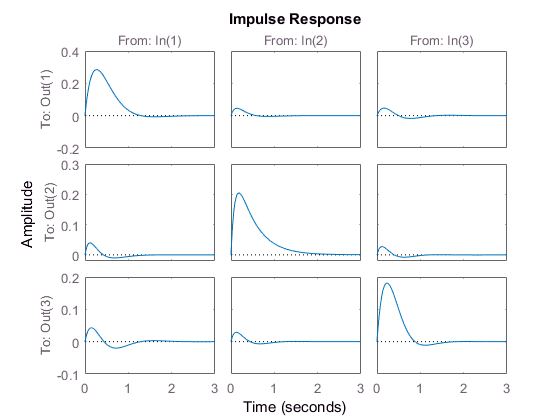

if diagdom, disp('Diagonal dominant');
end
impulse(feedback(sys,K_pd))